This file contains the MATLAB code and the output of the Examples 4.1, 4.2 and 4.3 from the manuscript.

**Example 4.1 (Table 1):**

Consider the following $$3 \times 3$$ matrix rational function, $$R(\lambda)= I \lambda^3+C_1 \lambda +C_0 + \frac{B_1}{(\lambda -1)^2} + \frac{B_2}{(\lambda -2)}$, where $C_0 =  \pmatrix{4 & 1 & 1  \cr  1 & 4 &1 \cr 1 & 1 & 4 }$, $C_1 =  \pmatrix{2 & 1 & 1  \cr  1 & 2 &1 \cr 1 & 1 & 2}$, $B_1 = B_2 = I$ $and 

poles $$a_1=1$, $a_2=2$ $of order $ $m_1 = 2$ $and $ $m_2=1$$ respectively. The associated block matrix $$C_R$ 
$is of size 

$$21 \times 21$$.  Throught this example we use the **spectral norm **on coefficient matrices.

We find the maximum of the moduli of eigenvalues of $$R(\lambda)$$ and obtain bounds on these values 

using **Theorems 3.8 **and** 3.9. **

**1. Maximum of absolute values of eigenvalues of **$$R(\lambda)$$**.**

a_1 = 1;
a_2 = 2;
m_1 = 2;
m_2 = 1;
Z = [0 0 0; 0 0 0; 0 0 0];
I = eye(3);
B_1 = I;
B_2 = I;
C_0 = [4 1 1; 1 4 1; 1 1 4];
C_1 = [2 1 1; 1 2 1; 1 1 2];

C_R = [(a_2)*I Z Z Z Z Z Z; Z (a_1)*I I Z Z Z Z; Z Z (a_1)*I Z -I Z Z; Z Z Z (a_1)*I -I Z Z; Z Z Z Z Z I Z; Z Z Z Z Z Z I; B_2 B_1 Z Z -C_0 -C_1 Z];
eig(C_R);
R=max(abs(eig(C_R)));

**2. Bound using Theorem 3.8.**

The associated real rational function is given by, $$q(x) = x^3 -||C_1||x - ||C_0||- \frac{||B_1||}{(x-1)^2}-\frac{||B_2||}{x-2}$$, whose 

largest real root is the bound given by Theorem 3.8. 

c_0 = norm(C_0);
c_1 = norm(C_1);
b_1 = norm(B_1);
b_2 = norm(B_2);
syms x 
eqn = x^3 - (c_1)*x - c_0 - (b_1)/(x-1)^2 -(b_2)/(x-2) ==0;
S=solve(eqn, x);
var = vpa(S);
max(abs(var));
R_1 = var(6,1);

**3. Bound using Theorem 3.9 (1).**

R_2 = max([1+a_1 1+a_2 b_1+b_2+c_0+c_1]);

**4. Bound using Theorem 3.9 (2).**

R_3 = max([a_1+b_1 a_2+b_2 1+a_1 1+a_2 1+c_1 c_0+m_1+m_2]);

**5. Bound using Theorem 3.9 (3).**

The numerical radius is:


nradius = 4.1597

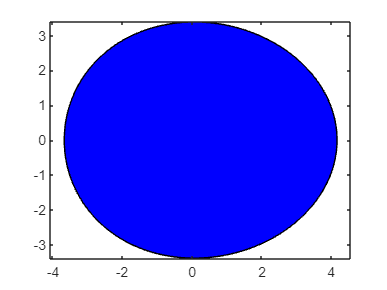

B_0 = [0 1 0; 0 0 1; c_0 c_1 0]; 
a = max(a_1+cos(pi/(m_1+1)), a_2+cos(pi/(m_2+1)));
b = nrange(B_0);

g = sqrt(m_1 + m_2);
d = sqrt((b_1)^2+ (b_2)^2);
R_4 = (1/2)*(a+4.1597+sqrt((a-4.1597)^2+(g+d)^2));

fprintf('The maximum of absolute values of eigenvalues is %.2f \n',R)

The maximum of absolute values of eigenvalues is 2.29 


fprintf('The bound using Theorem 3.8  is equal %.2f  \n',R_1)

The bound using Theorem 3.8  is equal 2.64  


fprintf('The bound using Theorem 3.9 (1) is %.2f  \n',R_2)

The bound using Theorem 3.9 (1) is 12.00  


fprintf('The bound using Theorem 3.9 (2) is %.2f  \n',R_3)

The bound using Theorem 3.9 (2) is 9.00  


fprintf('The bound using Theorem 3.9 (3) is %.2f  \n',R_4)

The bound using Theorem 3.9 (3) is 4.99  


**Example 4.1 (Table 2):**

 We obtain bounds on the moduli of eigenvalues of $$R(\lambda)$$  using results due to C. T. Le et al**. (see reference number 14 in the manuscript) . **

a_1 = 1;
a_2 = 2;
m_1 = 2;
m_2 = 1;
Z = [0 0 0; 0 0 0; 0 0 0];
I = eye(3);
B_1 = I;
B_2 = I;
C_0 = [4 1 1; 1 4 1; 1 1 4];
C_1 = [2 1 1; 1 2 1; 1 1 2];

C_R = [(a_2)*I Z Z Z Z Z Z; Z (a_1)*I I Z Z Z Z; Z Z (a_1)*I Z -I Z Z; Z Z Z (a_1)*I -I Z Z; Z Z Z Z Z I Z; Z Z Z Z Z Z I; B_2 B_1 Z Z -C_0 -C_1 Z];
eig(C_R);
R=max(abs(eig(C_R)));

A0 = -2*C_0 -I;
A1 = 5*C_0 -2*C_1 -I;
A2 = 5*C_1 -4*C_0 +I;
A3 = C_0 -2*I -4*C_1;
A4 = 5*I +C_1;
A5 = -4*I;
A6 = I;

**Bound using Theorem 3.1.**

g1 = [1 -norm(A5) -norm(A4) -norm(A3) -norm(A2) -norm(A1) -norm(A0)];
R1 = max(roots(g1));

**Bound using Theorem 3.2.**

C1 = [norm(A0) norm(A1) norm(A2) norm(A3) norm(A4) norm(A5)];
M1 = max(C1);
g2 = [1 -(1+M1) 0 0 0 0 0 M1];
R2 = max(1,max(roots(g2)));

**Bound using Theorem 3.3.**

R3 = 1+M1;

**Bound using Theorem 3.4.**

C2 = [norm(A0) norm(A1) norm(A2) norm(A3) norm(A4)];
M2 = max(C2);
R4 = 0.5*(1+norm(A5)+sqrt((1-norm(A5))^2 +4*M2));

**Bound using Corollary 3.4.2.**

C3 = [norm(A5 - A4) norm(A4 - A3) norm(A3 - A2) norm(A2 - A1) norm(A1 - A0) norm(A0)];
M3 = max(C3);
R5 = 0.5*(1+norm(I-A5)+sqrt((1-norm(I-A5))^2 +4*M3));

**Bound using Corollary 3.4.4.**

C4 = [norm(A5*A0) norm(A5*A1 -A0) norm(A5*A2 -A1) norm(A5*A3 -A2) norm(A5*A4 -A3) norm(A5*A5 -A4)];
M4 = max(C4);
R6 = 0.5*(1+sqrt(1+4*M4));

**Bound using Corollary 3.4.6.**

C5 = [norm((I-A5)*A0) norm((I-A5)*A1 +A0) norm((I-A5)*A2 +A1) norm((I-A5)*A3 +A2) norm((I-A5)*A4 +A3) norm((I-A5)*A5 +A4)];
M5 = max(C5);
R7 = 1+sqrt(M5);

**Bound using Corollary 3.2.1.**

C6 = [norm(A6 - A5) norm(A5 - A4) norm(A4 - A3) norm(A3 - A2) norm(A2 - A1) norm(A1 - A0) norm(A0)];
M6 = max(C6);
g3 = [1 -(1+ M6) 0 0 0 0 0 0 M6];
R8 = max(1,max(roots(g3)));

**Bound using Corollary 3.3.1.**

R9 = 1+R8;

fprintf('The bound using Theorem 3.1  is %.2f  \n',R1)

The bound using Theorem 3.1  is 5.91  


fprintf('The bound using Theorem 3.2 is %.2f  \n',R2)

The bound using Theorem 3.2 is 22.00  


fprintf('The bound using Theorem 3.3 is %.2f  \n',R3)

The bound using Theorem 3.3 is 22.00  


fprintf('The bound using Theorem 3.4 is %.2f  \n',R4)

The bound using Theorem 3.4 is 7.32  


fprintf('The bound using Corollary 3.4.2 is %.2f  \n',R5)

The bound using Corollary 3.4.2 is 9.16  


fprintf('The bound using Corollary 3.4.4 is %.2f  \n',R6)

The bound using Corollary 3.4.4 is 8.94  


fprintf('The bound using Corollary 3.4.6 is %.2f  \n',R7)

The bound using Corollary 3.4.6 is 10.59  


**Example 4.2 (Table 3):**

Consider the scalar rational function given by, $$r(\lambda) = \lambda^5 + \lambda +4 -\frac{1}{\lambda-1}+\frac{2}{(\lambda-1)^2}+\frac{3}{\lambda-3}+\frac{4}{(\lambda-3)^2}-\frac{1}{(\lambda-3)^3}$, $

with poles $$a_1 =1$$ and $ $a_2=3$  $of order $$m_1 =2$ $and $ $m_2=3$ $respectively.  The coefficients are $$c_0= -4$, $c_1 =-1$, $c_2=c_3=c_4=0$ and $b_1 ^{(1)} = b_{11} =1$, $b_2 ^{(1)}=b_{12} =-2$, $b_1 ^{(2)} =b_{21} =-3$, $b_2 ^{(2)}= b_{22} =-4$, $b_3 ^{(2)} = b_{23} =1$$.

The associated matrix $C_r$ is of size $14 \times 14
$. We find the maximum of absolute values of zeros of $r(\lambda)$ 

and obtain the bounds on zeros of $r(\lambda)$ using Theorems 3.3 and 3.5.

**1. Maximum of absolute values of zeros of **$r(\lambda).$

a1 = 1;
a2 = 3;
m1 = 2;
m2 = 3;
c0 = -4;
c1 = -1;
c2 = 0;
c3 = 0;
c4 = 0;
b11 = 1;
b12 = -2;
b21 = -3;
b22 = -4; 
b23 = 1;

syms x 
eqn = x^5 + x + 4 -1/(x-1)+ 2/(x-1)^2 +3/(x-3)+ 4/(x-3)^2-1/(x-3)^3  ==0;
S=solve(eqn, x);
var = vpa(S);
R = max(abs(var));

**2. Bound using Theorem 3.3 (1).**

R1 = max([1+abs(a1) 1+abs(a2) abs(c0)+abs(c1)+abs(b11)+abs(b12)+abs(b21)+abs(b22)+abs(b23)]);

**3. Bound using Theorem 3.3 (2).**

R2 = max([abs(a1)+abs(b11) abs(a1)+abs(b12) abs(a2)+abs(b21) abs(a2)+abs(b22) abs(a2)+abs(b23) 1+abs(a1) 1+abs(a2) 1+abs(c1) abs(c0)+m1+m2]);

**4. Bound using Theorem 3.5.**

The numerical radius is:


nradius = 2.2831

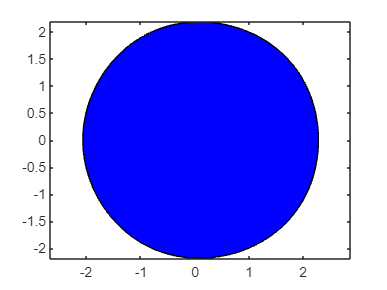

B0 =[0 1 0 0 0; 0 0 1 0 0; 0 0 0 1 0; 0 0 0 0 1; -4 -1 0 0 0];
a = max(a1+cos(pi/(m1+1)), a2+cos(pi/(m2+1)));
b = nrange(B0);

g = sqrt(m1+m2);
d = sqrt((abs(b11))^2+(abs(b12))^2+(abs(b21))^2+(abs(b22))^2+(abs(b23))^2);
R3 = (1/2)*(a+2.2831+sqrt((a-2.2831)^2+(g+d)^2));

**5. Bound using Theorem 3.1 of reference [6].**

 In this case the polynomial is,$$p(\lambda) = \lambda^{10}-11 \lambda^9+46\lambda^8-90\lambda^7+82\lambda^6-34\lambda^5+4\lambda^4+86\lambda^3-288\lambda^2+363\lambda-175$.$

The numerical radius is:


nradius = 47.4319

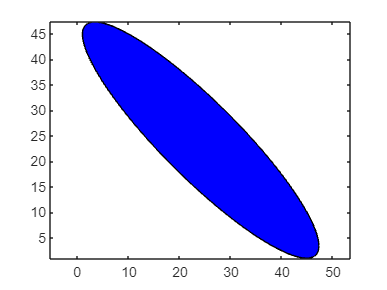

A = [11 -46; 1 0];
A';
A*A';
X=sqrtm(A'*A);
Y=sqrtm(A*A');
a= sqrt((175)^2+(363)^2+(288)^2+(86)^2+(4)^2+(34)^2+(82)^2+(90)^2);
b= nrange(X+i*Y);

c= 2+sqrt(2)*47.4319;
d= (sqrt(2)*47.4319-2)^2;
f= (1+a)^2;
R4= (1/4)*c+(1/4)*sqrt(d+4*f);

fprintf('The maximum of absolute values of zeros of r is %.2f \n',R)

The maximum of absolute values of zeros of r is 3.12 


fprintf('The bound using Theorem 3.3 (1)  is equal %.2f  \n',R1)

The bound using Theorem 3.3 (1)  is equal 16.00  


fprintf('The bound using Theorem 3.3 (2) is %.2f  \n',R2)

The bound using Theorem 3.3 (2) is 9.00  


fprintf('The bound using Theorem 3.5 is %.2f  \n',R3)

The bound using Theorem 3.5 is 6.96  


fprintf('The bound using Theorem 3.1 of Frakis et al. %.2f  \n',R4)

The bound using Theorem 3.1 of Frakis et al. 277.47  


**Example 4.2 :**

 We obtain bounds on the moduli of zeros of $$$r(\lambda)$$$ using results due to C. T. Le et al**. **Note that zeros of  $r(\lambda)$ are the same as the zeros of $$p(\lambda) = \lambda^{10}-11 \lambda^9+46\lambda^8-90\lambda^7+82\lambda^6-34\lambda^5+4\lambda^4+86\lambda^3-288\lambda^2+363\lambda-175$.$

syms x
eqn = x^5 + x + 4 -1/(x-1)+ 2/(x-1)^2 +3/(x-3)+ 4/(x-3)^2-1/(x-3)^3  ==0;
S=solve(eqn, x);
var = vpa(S);
R = max(abs(var));
c0 = 175;
c1 = -363;
c2 = 288;
c3 = -86;
c4 = -4;
c5 = 34;
c6 = -82;
c7 = 90;
c8 = -46;
c9 = 11;

**The maximum of the moduli of zeros of **$r(\lambda)$**.**

r = max(abs(var));

**Bound using Corollary 3.4 (1) of our manuscript.**

r1 = max(1, abs(c9)+abs(c8)+abs(c7)+abs(c6)+abs(c5)+abs(c4)+abs(c3)+abs(c2)+abs(c1)+abs(c0));

**Bound using Corollary 3.4 (2) of our manuscript.**

r2 = max([abs(c0) 1+abs(c1) 1+abs(c2) 1+abs(c3) 1+abs(c4) 1+abs(c5) 1+abs(c6) 1+abs(c7) 1+abs(c8) 1+abs(c9)]);

**Bound using Corollary 3.6 of our manuscript.**

r3 = 0.5*(cos(pi/10)+abs(c9)+sqrt((cos(pi/10)-abs(c9))^2+(1+sqrt(abs(c0)^2 + abs(c1)^2+ abs(c2)^2+ abs(c3)^2+ abs(c4)^2+ abs(c5)^2+ abs(c6)^2+ abs(c7)^2+ abs(c8)^2))^2));

**Bound due to Cauchy (Equation 3.8 in the manuscript).**

r4 = 1 + max([abs(c0) abs(c1) abs(c2) abs(c3) abs(c4) abs(c5) abs(c6) abs(c7) abs(c8) abs(c9)]);

**Bound due to Carmaichael and Mason (Equation 3.9 in the manuscript).**

r5 = sqrt(1+(abs(c0))^2+(abs(c1))^2+(abs(c2))^2+(abs(c3))^2+(abs(c4))^2+(abs(c5))^2+(abs(c6))^2+(abs(c7))^2+(abs(c8))^2+(abs(c9))^2);

**Bound due to Montel (Equation 3.10 in the manuscript).**

r6 = max(1, abs(c9)+abs(c8)+abs(c7)+abs(c6)+abs(c5)+abs(c4)+abs(c3)+abs(c2)+abs(c1)+abs(c0));

**Bound due to Frakis et al. (Equation 3.11 in the manuscript).**

The numerical radius is:


nradius = 47.4319

A = [c9 c8; 1 0];
A';
A*A';
X=sqrtm(A'*A);
Y=sqrtm(A*A');
a= sqrt((abs(c0))^2 + (abs(c1))^2 + (abs(c2))^2 + (abs(c3))^2 + (abs(c4))^2 + (abs(c5))^2 + (abs(c6))^2 + (abs(c7))^2);
b= nrange(X+i*Y);

c= 2+(sqrt(2)*47.4319);
d= ((sqrt(2)*47.4319)-2)^2;
f= (1+a)^2;
r7= (1/4)*c+(1/4)*sqrt(d+4*f);

fprintf('The bound using Corollary 3.4 (1)  is %.2f  \n',r1)

The bound using Corollary 3.4 (1)  is 1179.00  


fprintf('The bound using Corollary 3.4 (2)  is %.2f  \n',r2)

The bound using Corollary 3.4 (2)  is 364.00  


fprintf('The bound using Corollary 3.6 is %.2f  \n',r3)

The bound using Corollary 3.6 is 266.74  


fprintf('The bound due to Cauchy is %.2f  \n',r4)

The bound due to Cauchy is 364.00  


fprintf('The bound due to Carmichael and Mason is %.2f  \n',r5)

The bound due to Carmichael and Mason is 520.55  


fprintf('The bound due to Montel is %.2f  \n',r6)

The bound due to Montel is 1179.00  


fprintf('The bound due to Frakis et al. is %.2f  \n',r7)

The bound due to Frakis et al. is 277.47  


fprintf('***')

***

**Example 4.3 (Table 4).**

We consider two scalar complex polynomials and derive bounds on the moduli of zeros of these polynomials using the methods metioned in Section 2 of the manuscript. Let  $p_1(\lambda) = \lambda ^3 -2i \lambda ^2 - (1+i) \lambda -1$ and $p_2(\lambda) =  \lambda ^4 -\lambda^2-0.5 \lambda -i$.

We first consider $p_1(\lambda)$.

c0 = 1;
c1 = 1+i;
c2 = 2i;
p = [1 -c2 -c1 -c0];
roots(p);

**The maximum of the moduli of zeros of **$p_1(\lambda)$**.**

r = max(abs(roots(p)));

**Bound using Corollary 3.4 (1) of our manuscript.**

r1 = max(1, abs(c2)+abs(c1)+abs(c0));

**Bound using Corollary 3.4 (2) of our manuscript.**

r2 = max([abs(c0) 1+abs(c1) 1+abs(c2)]);

**Bound using Corollary 3.6 of our manuscript.**

r3 = 0.5*(cos(pi/3)+abs(c2)+sqrt((cos(pi/3)-abs(c2))^2+(1+sqrt(abs(c0)^2 + abs(c1)^2))^2));

**Bound due to Cauchy (Equation 3.8 in the manuscript).**

r4 = 1 + max([abs(c0) abs(c1) abs(c2)]);

**Bound due to Carmaichael and Mason (Equation 3.9 in the manuscript).**

r5 = sqrt(1+(abs(c0))^2+(abs(c1))^2+(abs(c2))^2);

**Bound due to Montel (Equation 3.10 in the manuscript).**

r6 = max(1, abs(c2)+abs(c1)+abs(c0));

**Bound due to Frakis et al. (Equation 3.11 in the manuscript).**

The numerical radius is:


nradius = 3.2255

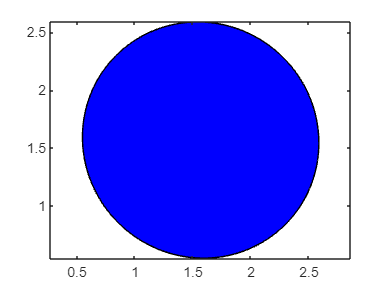

A = [c2 c1; 1 0];
A';
A*A';
X=sqrtm(A'*A);
Y=sqrtm(A*A');
a= sqrt((abs(c0))^2);
b= nrange(X+i*Y);

c= 2+(sqrt(2)*3.2255);
d= ((sqrt(2)*3.2255)-2)^2;
f= (1+a)^2;
r7= (1/4)*c+(1/4)*sqrt(d+4*f);

fprintf('The maximum of the moduli of zeros of p_1 is %.2f \n',r)

The maximum of the moduli of zeros of p_1 is 1.44 


fprintf('The bound using Corollary 3.4 (1)  is %.2f  \n',r1)

The bound using Corollary 3.4 (1)  is 4.41  


fprintf('The bound using Corollary 3.4 (2)  is %.2f  \n',r2)

The bound using Corollary 3.4 (2)  is 3.00  


fprintf('The bound using Corollary 3.6 is %.2f  \n',r3)

The bound using Corollary 3.6 is 2.81  


fprintf('The bound due to Cauchy is %.2f  \n',r4)

The bound due to Cauchy is 3.00  


fprintf('The bound due to Carmichael and Mason is %.2f  \n',r5)

The bound due to Carmichael and Mason is 2.83  


fprintf('The bound due to Montel is %.2f  \n',r6)

The bound due to Montel is 4.41  


fprintf('The bound due to Frakis et al. is %.2f  \n',r7)

The bound due to Frakis et al. is 2.83  


fprintf('***')

***

We now consider polynomial $p_2(\lambda) =  \lambda ^4 -\lambda^2-0.5 \lambda -i$.

c0 = i;
c1 = 0.5;
c2 = 1;
c3 = 0;
p=[1 -c3 -c2 -c1 -c0];
roots(p);

**The maximum of the moduli of zeros of **$p_2(\lambda)$**.**

r = max(abs(roots(p)));

**Bound using Corollary 3.4 (1) of our manuscript.**

r1 = max(1, abs(c3)+abs(c2)+abs(c1)+abs(c0));

**Bound using Corollary 3.4 (2) of our manuscript.**

r2 = max([abs(c0) 1+abs(c1) 1+abs(c2) 1+abs(c3)]);

**Bound using Corollary 3.6 of our manuscript.**

r3 = 0.5*(cos(pi/4)+abs(c3)+sqrt((cos(pi/4)-abs(c3))^2+(1+sqrt(abs(c0)^2 + abs(c1)^2 +abs(c2)^2))^2));

**Bound due to Cauchy (Equation 3.8 in the manuscript).**

r4 = 1 + max([abs(c0) abs(c1) abs(c2) abs(c3)]);

**Bound due to Carmaichael and Mason (Equation 3.9 in the manuscript).**

r5 = sqrt(1+(abs(c0))^2+(abs(c1))^2+(abs(c2))^2+(abs(c3))^2);

**Bound due to Montel (Equation 3.10 in the manuscript).**

r6 = max(1, abs(c3)+abs(c2)+abs(c1)+abs(c0));

**Bound due to Frakis et al. (Equation 3.11 in the manuscript).**

The numerical radius is:


nradius = 1.4142

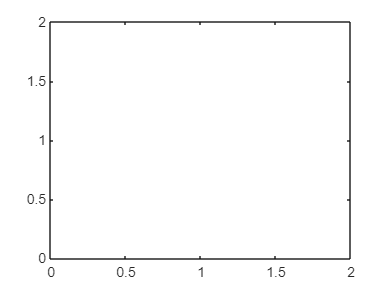

A = [c3 c2; 1 0];
A';
A*A';
X=sqrtm(A'*A);
Y=sqrtm(A*A');
a= sqrt((abs(c0))^2 + (abs(c1))^2);
b= nrange(X+i*Y);

c= 2+(sqrt(2)*1.4142);
d= ((sqrt(2)*1.4142)-2)^2;
f= (1+a)^2;
r7= (1/4)*c+(1/4)*sqrt(d+4*f);

fprintf('The maximum of the moduli of zeros of p_ is %.2f \n',r)

The maximum of the moduli of zeros of p_ is 1.29 


fprintf('The bound using Corollary 3.4 (1)  is %.2f  \n',r1)

The bound using Corollary 3.4 (1)  is 2.50  


fprintf('The bound using Corollary 3.4 (2)  is %.2f  \n',r2)

The bound using Corollary 3.4 (2)  is 2.00  


fprintf('The bound using Corollary 3.6 is %.2f  \n',r3)

The bound using Corollary 3.6 is 1.65  


fprintf('The bound due to Cauchy is %.2f  \n',r4)

The bound due to Cauchy is 2.00  


fprintf('The bound due to Carmichael and Mason is %.2f  \n',r5)

The bound due to Carmichael and Mason is 1.80  


fprintf('The bound due to Montel is %.2f  \n',r6)

The bound due to Montel is 2.50  


fprintf('The bound due to Frakis et al. is %.2f  \n',r7)

The bound due to Frakis et al. is 2.06  
